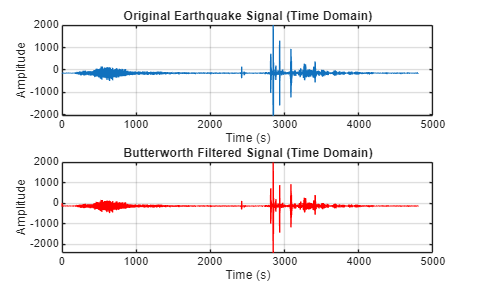

% Load SAC file
sac_file = 'WANC_SHZ_2004_361_01-10-00.SAC';
[data, header] = readsac(sac_file);
% Extract sample period
ts = header.DELTA;
fs = 1/ts;

filter_order = 4;     % order choice
f_cutoff = 10;        % cutoff frequency in Hz
Wn = f_cutoff / (fs/2); % Normalized cutoff 

% Generate coefficients 
[b, a] = butter(filter_order, Wn, 'low');

%Filter
filtered_signal_iir = filter(b, a, data);

% Plotting results
t = (0:length(data)-1) * (1/fs); % time vector

figure;
subplot(2,1,1);
plot(t, data);
title('Original Earthquake Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, filtered_signal_iir, 'r');
title('Butterworth Filtered Signal (Time Domain)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


%Discussion
%For problem three following some research I decided to use a 4th order
%Butterworth filter since it provides a maximally flat signal within its
%passband.  This would ensure that there would be a lot of reduced rippling
%that was not wanted within the design.  When comparing the original signal
%to the filtered signal the Butterworth appears to smooth out the data
%while maintaing the overall shape of the primary waves.
%Sources: MathWorks "Butterworth Filter Design" and GenAI for
%troubleshooting and research